# HW 3

## Problem 1: Truth Tables

As an example let's assume we have a 100 photos, some of birds and some of people. In a truth table you assume you can categorize the true answer—let's say you pay an undergraduate to sort the photos into birds and people. Then you want to have an automated sorting algorithm. However that works, whether it is by looking a the color at the center of photo or using a neural network (NN), it will also sort the photos but imperfectly.

NN = {'NN Bird';'NN Person'};
TrueBird = [45;3];
TruePerson = [5;47];
Table1 = table(TrueBird,TruePerson,'RowNames',NN)

Table1 = 2×2 table
                 TrueBird    TruePerson
                 ________    __________

    NN Bird         45            5    
    NN Person        3           47    


There are 48 birds and 52 People (columns), and there are 8 miscategorizations. The NN called three of the birds people, and 5 of the people birds.

This is useful because it not only shows the number of errors, but the type, and not all errors are created equal. Let's say our identification system is being used to keep birds from escaping the aviary at the zoo by locking the aviary door when a bird is trying to escape. We *really* don't want to let birds escape, but locking a person in for 30 extra seconds is not a big deal. In this case false bird identification is not so bad, but false person identification lets a bird escape.

Let's say the above truth table is the current system, and you've developed a new algorithm (NA) with the following truth table:

NN = {'NN Bird';'NN Person'};
TrueBird = [47;1];
TruePerson = [11;42];
Table2 = table(TrueBird,TruePerson,'RowNames',NN)

Table2 = 2×2 table
                 TrueBird    TruePerson
                 ________    __________

    NN Bird         47           11    
    NN Person        1           42    


### 1a) Which algorithm makes the fewest mistakes?

In the first table, there are 3 person miscategorizations and 5 bird miscategorizations, so overall there are 8 mistakes.

In the second table, there is 1 person miscategorization and 11 bird miscategorizations. Overall, this makes 12 mistakes. 

By these numbers, there are fewer mistakes in the first algorithm. 

### 1b) Which algorithm is better for the zoo? Explain.

The zoo is more concerned with not letting birds escape, so false person identifications are worse than false bird identifications. 

The first algorithm miscategorizes 5/52 people as birds and 3/48 birds as people. The second algorithm miscategorizes 11/53 people as birds and 1/48 birds as people. 

To decide which algorithm is better for the zoo, I compare the ratios of the misidentified birds, 3/48 to 1/48. The proportion is lower for the second algorithm, so table 2 is better for the zoo. 

### 1c) During the pandemic the number of visitors plummets, and it is only the zoo keeper visiting. So instead of 52% of the photos taken at the aviary door being people, it is now only 1%. Make new truth tables for both algorithms.

TotalPeople = 2496;
TotalBirds = 99*TotalPeople;

TrueBird = [TotalBirds - (3/48)*TotalBirds;(3/48)*TotalBirds];
TruePerson = [(5/52)*TotalPeople;TotalPeople - (5/52)*TotalPeople];
Algorithm1_Table = table(TrueBird,TruePerson,'RowNames',NN)

Algorithm1_Table = 2×2 table
                  TrueBird     TruePerson
                 __________    __________

    NN Bird      2.3166e+05        240   
    NN Person         15444       2256   



TotalPeople = 2544;
TotalBirds = 99*TotalPeople;

TrueBird = [TotalBirds - (1/48)*TotalBirds;(1/48)*TotalBirds,];
TruePerson = [(11/53)*TotalPeople;TotalPeople - (11/53)*TotalPeople];
Algorithm2_Table = table(TrueBird,TruePerson,'RowNames',NN)

Algorithm2_Table = 2×2 table
                  TrueBird     TruePerson
                 __________    __________

    NN Bird      2.4661e+05        528   
    NN Person          5247       2016   


## Problem 2: Analytical Solutions

In the last lab we explored how to numerically calculate the pdf of a summed or averaged observation through repeated convolutions. But sometimes the convolution has an analytical solution. We could have found this out by either using a sharp pencil and doing the convolution integral by hand, or by looking it up in a table (much easier).

Having an analytic answer is much nicer when they exist, so it is always good to look and see if it exists. Further, sums and averages are only some of the mathematical operations that we can perform. In this section we will do an internet scavenger hunt to find the analytic pdf for some interesting distributions.

### 2a) What is the pdf of the sum of two identical exponential distributions?

The sum of two identical exponential distributions is determined analytically by: ${f_z \left(z\right)=\lambda }^2 {\mathrm{ze}}^{-\lambda z}$. This distribution is an Erlang, characterized by $n=2$ and $\beta$. Since MATLAB doesn't have a makedist for Erlang, I'm using "gamma" with $\alpha =n=2$ since I'm only summing two exponentials and an Erlang is equivalent to a gamma distribution where the $\alpha$of the gamma is the n of the Erlang. 

For example,

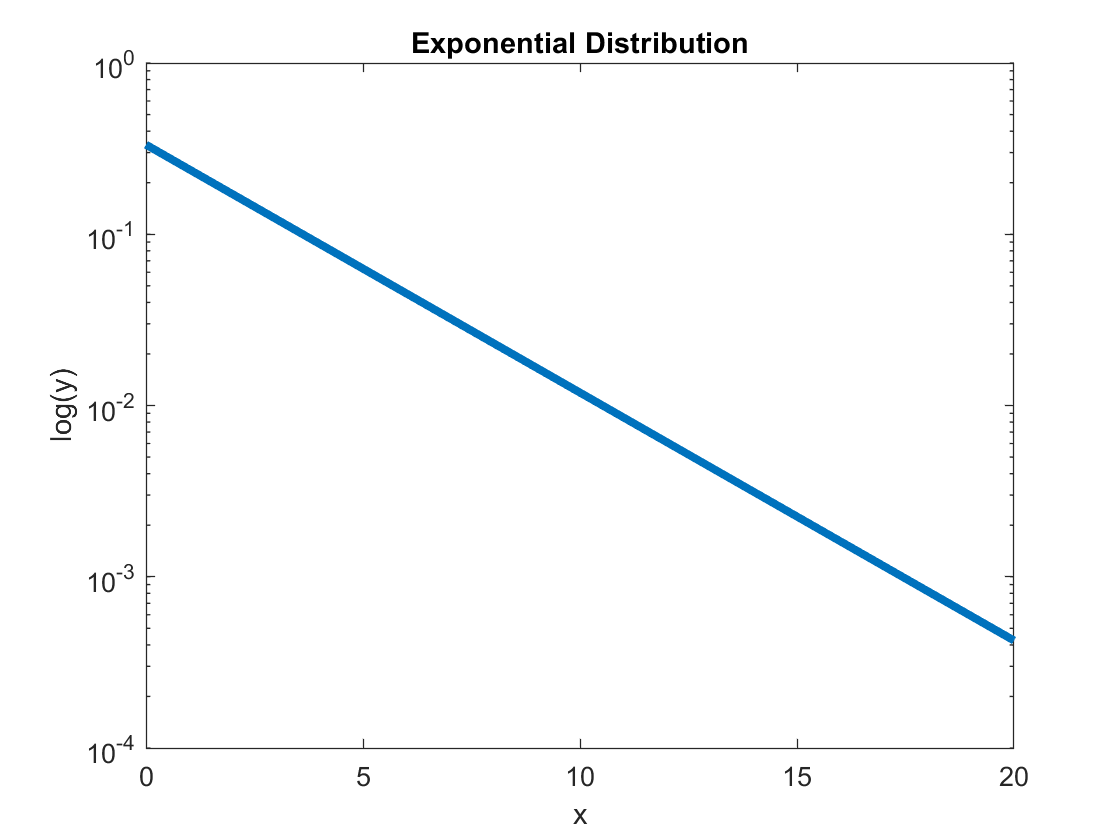

expon = makedist("Exponential","mu",3);
x = 0:0.1:20;

plot(x,pdf(expon,x),"LineWidth",3)
set(gca,'YScale','log')
title('Exponential Distribution')
xlabel('x')
ylabel('log(y)')

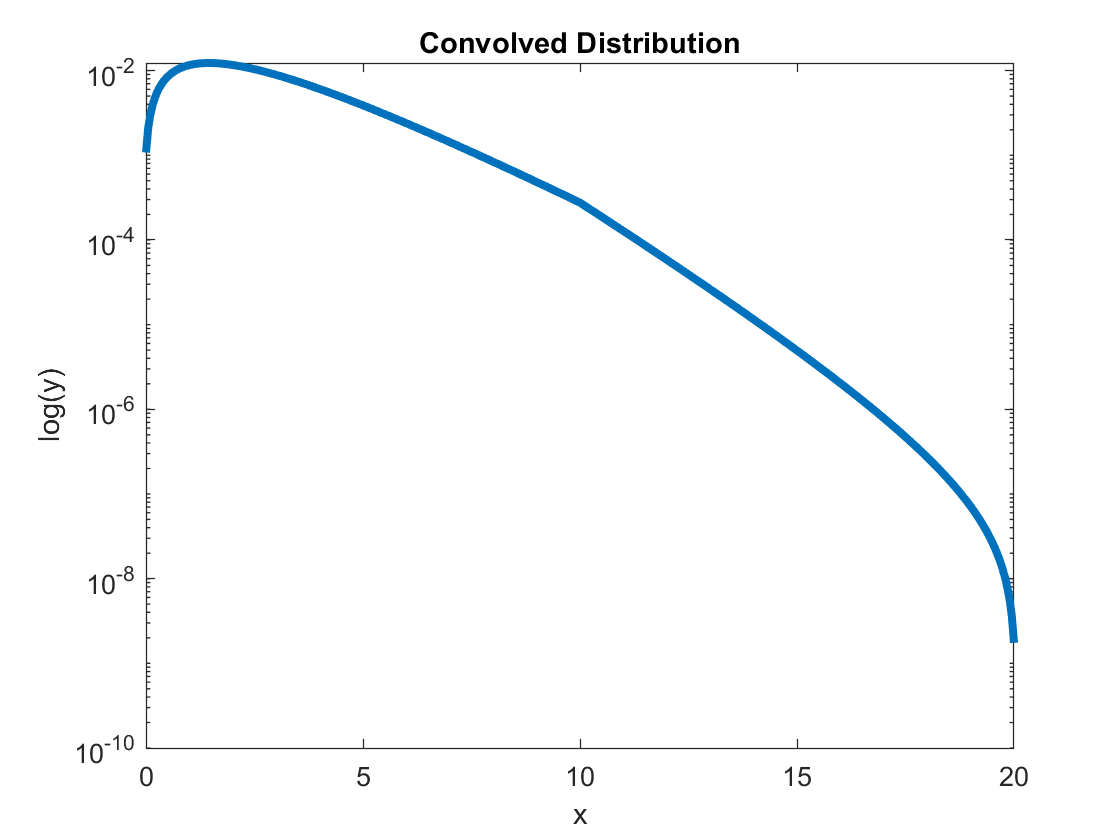


base = pdf(expon,x);
base = base/sum(base);
comb = base;

for i = 2
    comb = conv(comb,base,"full");
end

cx = 0:0.1/i:20;
plot(cx,comb,"LineWidth",3)
set(gca,'YScale','log')
title('Convolved Distribution')
xlabel('x')
ylabel('log(y)')

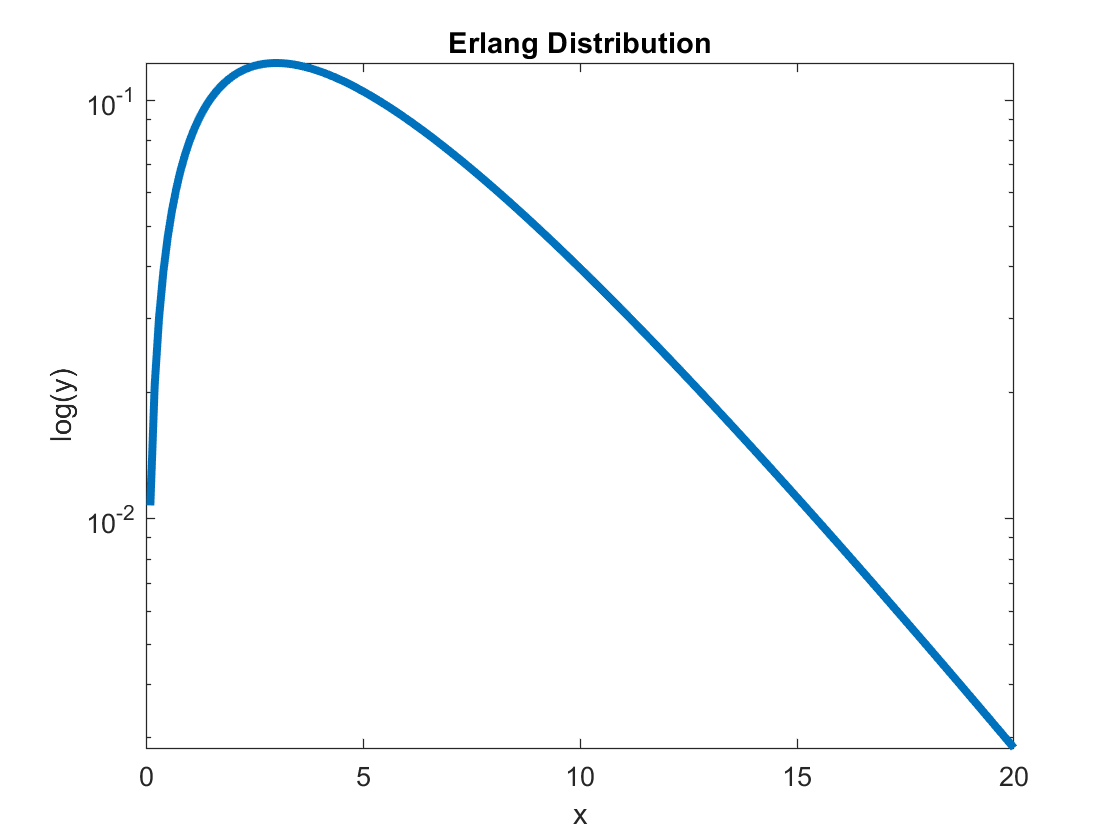


summed = makedist("Gamma","a",2,"b",3);
plot(x,pdf(summed,x),"LineWidth",3)
set(gca,'YScale','log')
title('Erlang Distribution')
xlabel('x')
ylabel('log(y)')

### 2b) What is the pdf of the ratio of two zero-mean unity variance normal distributions $\frac{X_1 }{X_2 }$?

Distribution of a standard normal distribution divided by a standard normal distribution is a Standard Cauchy distribution, which I determined by consulting the CRC diagram (and Wikipedia). Like the Erlang in 2a, there is not "Cauchy" distribution, so I used the "tLocationScale" with $\nu =1$, which is equivalent. 

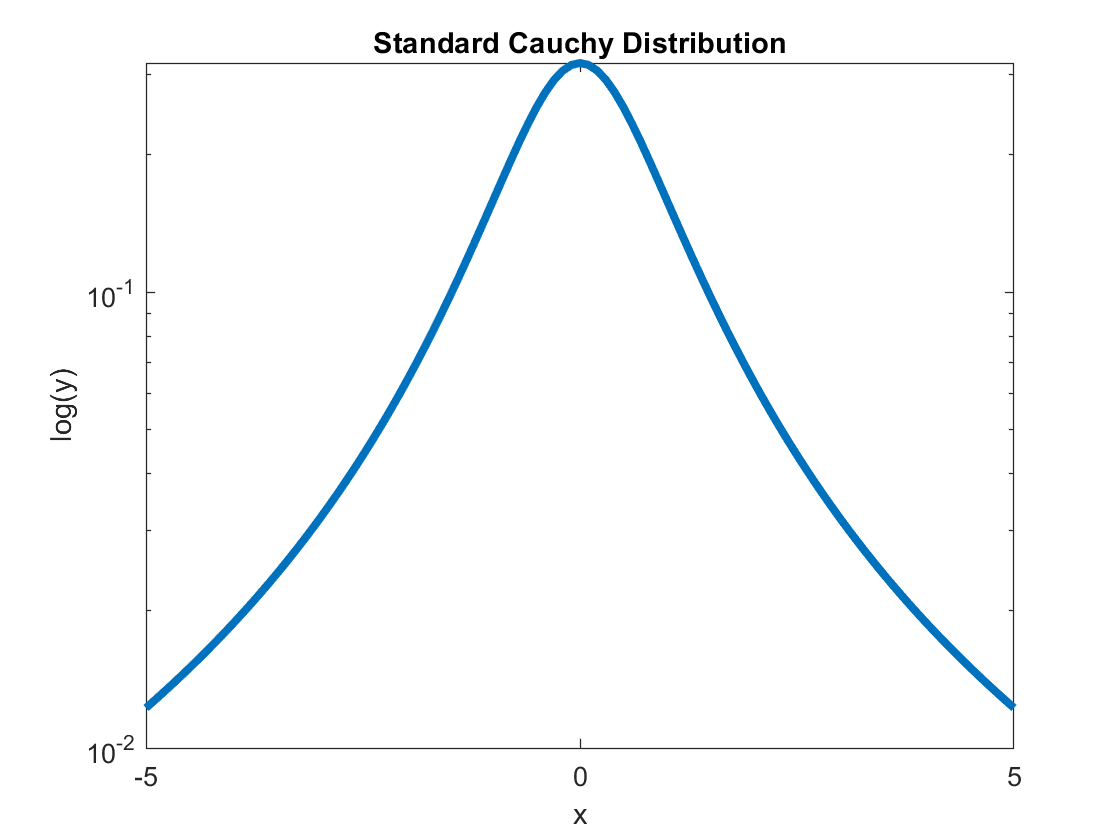

x = -5:0.1:5;

div = makedist("tLocationScale","nu",1);
plot(x,pdf(div,x),"LineWidth",3)
set(gca,'YScale','log')
title('Standard Cauchy Distribution')
xlabel('x')
ylabel('log(y)')

### 2c) So far we have looked at 1D probability distributions, but it is possible to have a multi-dimensional vector distribution. A simple first introduction is the 2D Guassian; it looks like a smeared spot. Mathematically this is given by $X\hat{i} +Y\hat{j}$ where both $X$ and $Y$ are drawn from 1D Gaussian distributions. If I measure the amplitude of this vector, what is its pdf? (Hint, the amplitude is always positive.)